**The following are symbols in use**

s=tf('s');

**The following are the constant varible which will be taken in use**

K = 0.530516; % Motorconstant
La = 3.3475; % Inductance in mH
Ra = 6.8144; % Resistance in ohm
B = 0.000931; % Motror frictions koefficient
J =0.0019; % Motor intertimoment kg*m^2

J_bcs= 0.0889; % Intertimoment for pan/tilt i best kg*m^2
J_wcs= 0.0946; % Intertimoment for pan/tilt i worst kg*m^2

**The following are the performance specifications**

tr = 1;  % Rise time
Mp = 0.1;   % Overshoot
ts = 3;   % Settling time

% Below is in freqency domain

wn = 1.8/tr;
zeta = sqrt(((log(Mp)/-pi)^2)/(1+(log(Mp)/-pi)^2));
sigma = 4.6/ts;

**The following is the three transfer functions**

TF_p =K/(s*((Ra + La)*(J*s + B) + K)); %Position
TF_v =K/((Ra + La)*(J*s+B)+K); %Velocity
TF_c =1/(Ra + La*s + ((K*s)/(J*s^2+B*s))); %Current

**The following is the begining of finding a suitable controller for the system**

Encoder =200 khz

ADC_current = 1 mhz

ca 5 gange hurtigere

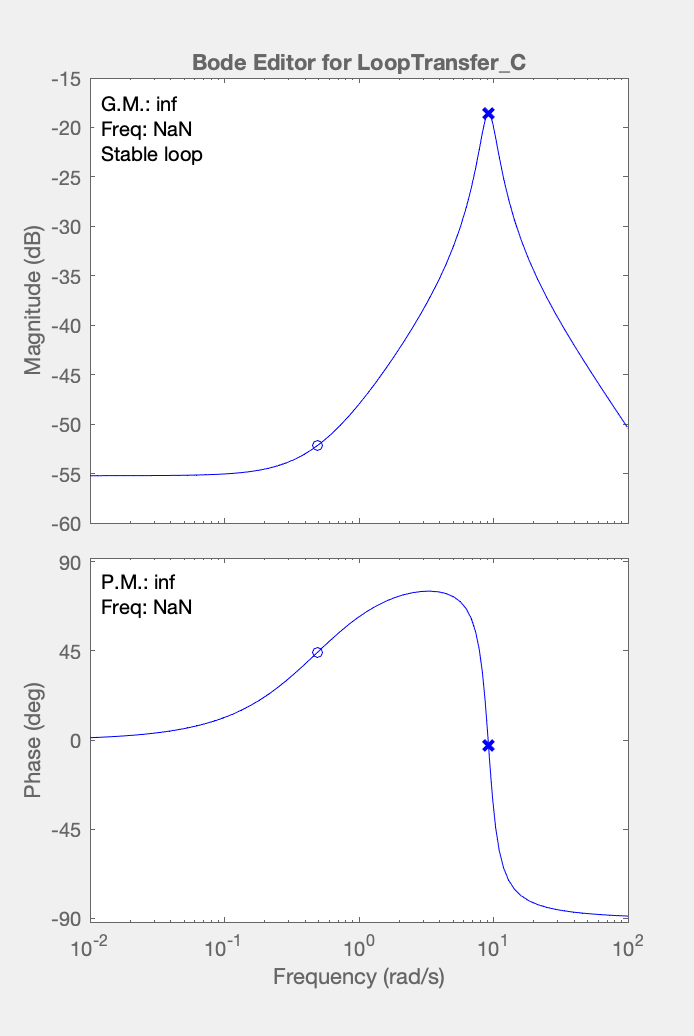

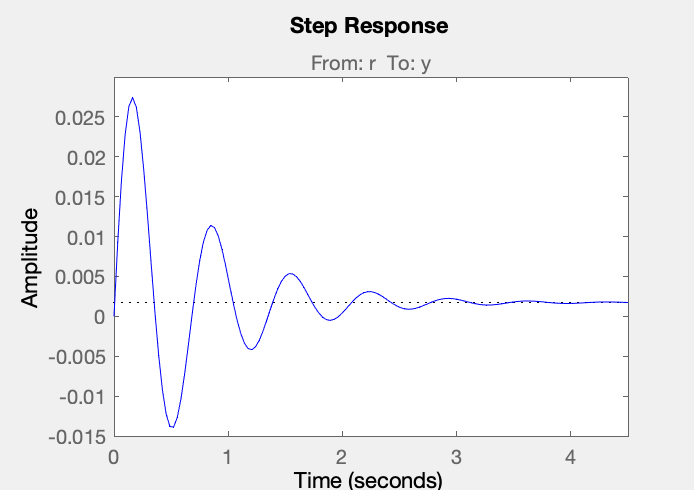

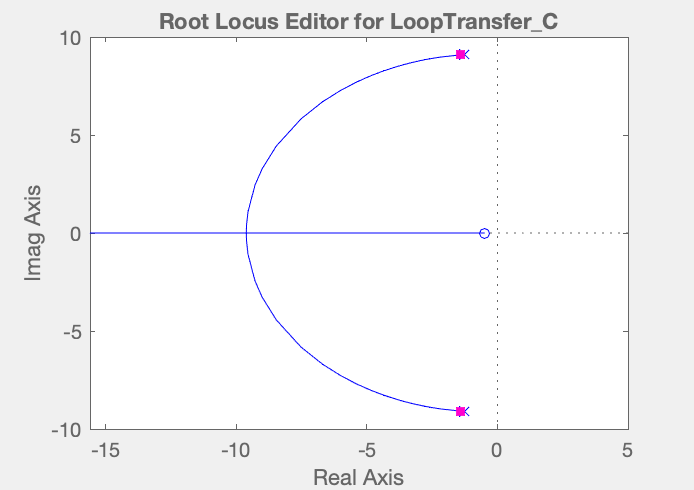


controlSystemDesigner(TF_c)

%COntrollability
K = 0.530516; % Motorconstant
La = 3.3475; % Inductance in mH
Ra = 6.8144; % Resistance in ohm
B = 0.000931; % Motror frictions koefficient
J =0.0019; % Motor intertimoment kg*m^2

%første tilgang til løsningen
sysNum = [0 0 K]

sysNum =          0         0    0.5305


sysDen = [(Ra*J + La*J), (Ra*B + La*B + K) 0]

sysDen =     0.0193    0.5400         0


s =
 
  s
 
Continuous-time transfer function.



sysLigning =
 
           0.5305
  ------------------------
  0.02096 s^2 + 0.006344 s
 
Continuous-time transfer function.



sysLigning =
 
           0.5305
  ------------------------
  0.02096 s^2 + 0.006344 s
 
Continuous-time transfer function.



sysFrac = tf(sysNum,sysDen) %Der er en afvigelse!

sysFrac =
 
         0.5305
  --------------------
  0.01931 s^2 + 0.54 s
 
Continuous-time transfer function.



[A,B,C,D] = tf2ss(sysNum,sysDen)

A =   -27.9670         0
    1.0000         0


B =      1
     0


C =          0   27.4770


D = 0

controllability = ctrb(A,B)

controllability =     1.0000  -27.9670
         0    1.0000



%%andne tilgang til løsningen med afvigelse
s = tf('s')
sysLigning = K/(Ra*J*s^2 + La*J*s^2 + Ra*B*s + La*B*s * K*s) %DET ER DET SAMME! (hvilket var meningen)
sysLigning = tf(sysLigning) %DET ER DET SAMME! (hvilket var meningen)
sysLigningNum = [0 0 K]

sysLigningNum =          0         0    0.5305


sysLigningDenum = [0.02096 0.006344 0]

sysLigningDenum =     0.0210    0.0063         0


[A,B,C,D] = tf2ss(sysLigningNum, sysLigningDenum)

A =    -0.3027         0
    1.0000         0


B =      1
     0


C =          0   25.3109


D = 0

controllability = ctrb(A,B)

controllability =     1.0000   -0.3027
         0    1.0000
